#### PRBS

T=20000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_
%punto de operacion u=0.5
S0=0.1431;
E0=0.0092;
I0=0.0092;
R0=0.8384;


Control_U=3;
time = (0:10:T)';
beta_U = timetable(seconds(time),zeros(numel(time),1));
beta_seno = timetable(seconds(time),zeros(numel(time),1));
Rango_PRBS=[0.3 0.7];
dir_modelo = "SEIRS.slx";
Sim_Data_PRBS=sim(dir_modelo);

Infectados_PRBS=Sim_Data_PRBS.I.signals.values;
Entrada_PRBS=Sim_Data_PRBS.Entrada_U.signals.values;
t_entrada=Sim_Data_PRBS.Entrada_U.time;
t_PRBS=Sim_Data_PRBS.I.time;
Y_PRBS=Infectados_PRBS;
U_PRBS=Entrada_PRBS;

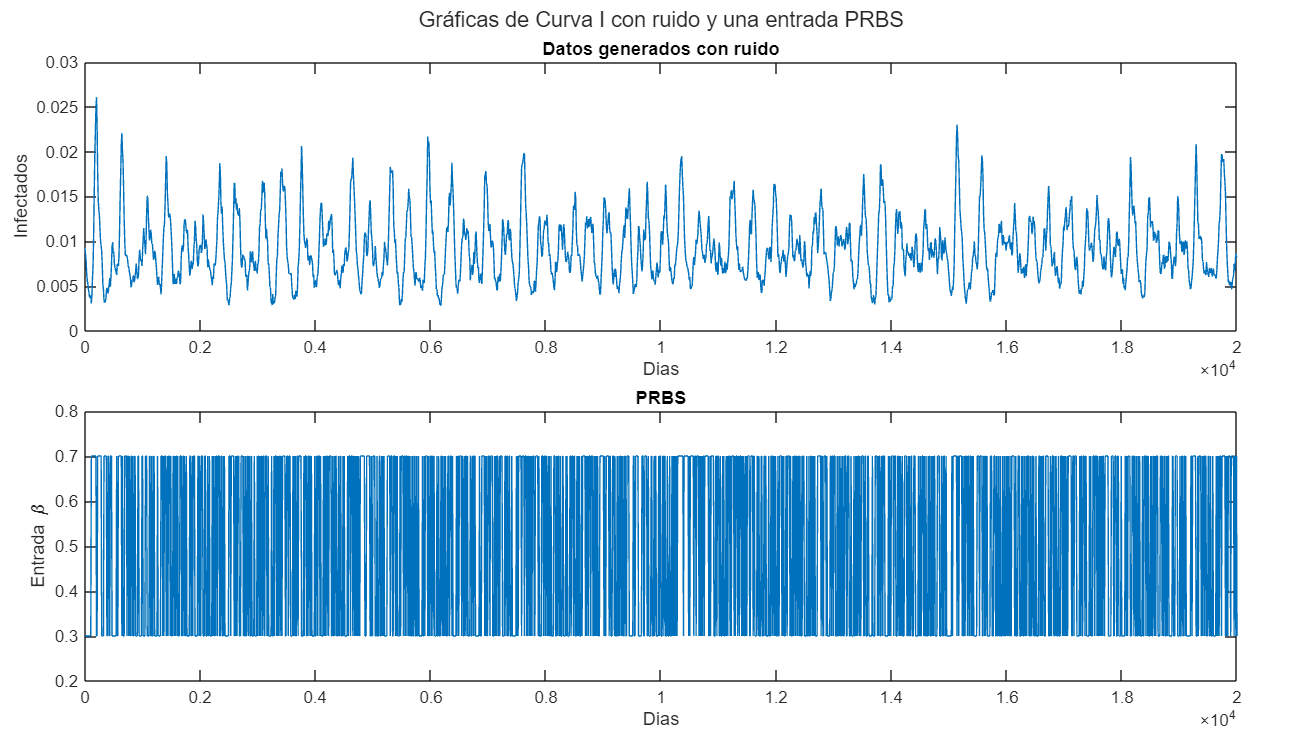

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");

nexttile,plot(t_PRBS,Infectados_PRBS),xlabel('Dias');ylabel('Infectados');title('Datos generados con ruido');

nexttile
plot(t_entrada,Entrada_PRBS),ylim([0.2 0.8]);xlabel('Dias');ylabel('Entrada \beta');title('PRBS');sgtitle('Gráficas de Curva I con ruido y una entrada PRBS');

#### Escalon

T=2000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_
%punto operacion u=0.3
S0=0.2004;
E0=0.0086;
I0=0.0086;
R0=0.7824;

%u=0.6;
Control_U=1;
time = (0:10:T)';
beta_U = timetable(seconds(time),(time>=100)*0.4+0.3);
beta_seno = timetable(seconds(time),zeros(numel(time),1));
dir_modelo = "SEIRS.slx";
Sim_Data_Escalon=sim(dir_modelo);


Infectados_Escalon=Sim_Data_Escalon.I.signals.values;
Entrada_Escalon=Sim_Data_Escalon.Entrada_U.signals.values;
t_entrada=Sim_Data_Escalon.Entrada_U.time;
t_escalon=Sim_Data_Escalon.I.time;
Y_Escalon=Infectados_Escalon;
U_Escalon=Entrada_Escalon;


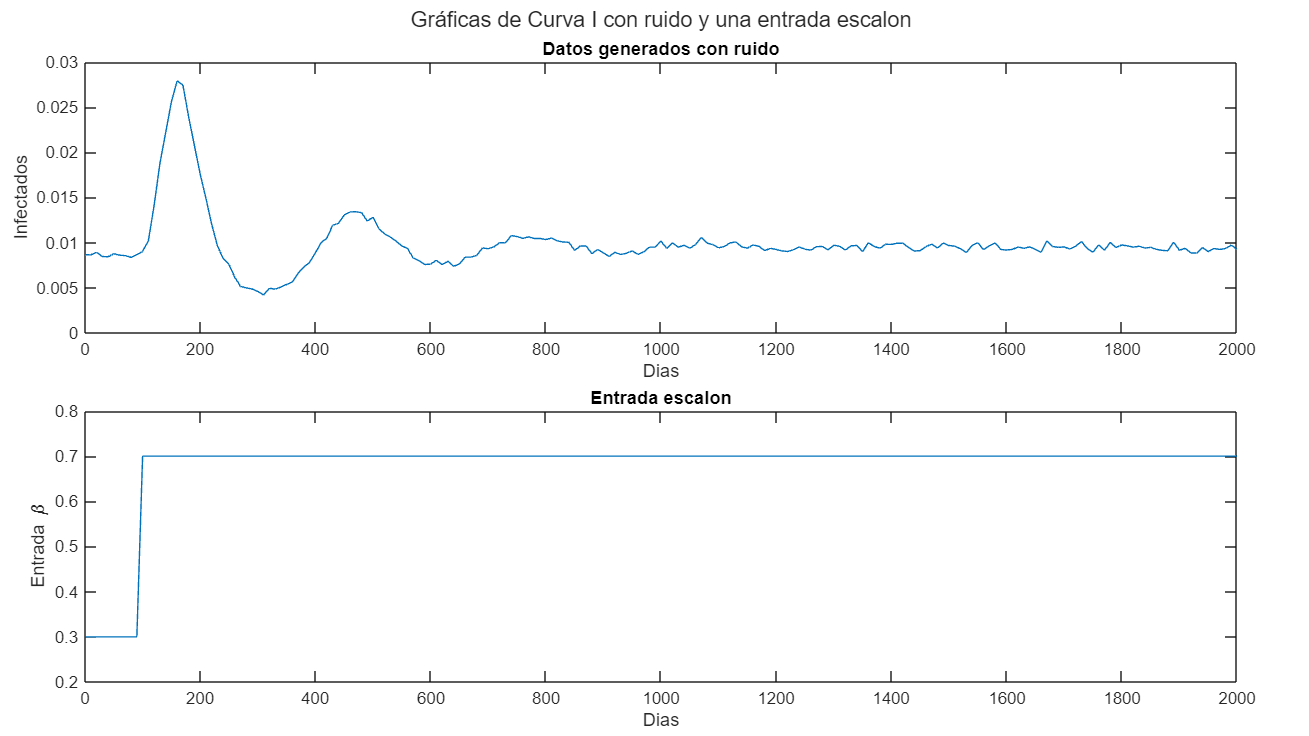

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");

nexttile,plot(t_escalon,Infectados_Escalon),xlabel('Dias');ylabel('Infectados');title('Datos generados con ruido');

nexttile
plot(t_entrada,Entrada_Escalon),ylim([0.2 0.8]);xlabel('Dias');ylabel('Entrada \beta');title('Entrada escalon');sgtitle('Gráficas de Curva I con ruido y una entrada escalon');

#### Seno

T=5000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_
%punto de operacion u=0.5
S0=0.1431;
E0=0.0092;
I0=0.0092;
R0=0.8384;

Control_U=2;
time = (0:10:T)';
beta_U =timetable(seconds(time),zeros(numel(time),1));
beta_seno=timetable(seconds(time),-sin(time*2*pi/1000)*0.2+0.5);
dir_modelo = "SEIRS.slx";
Sim_Data_Escalon=sim(dir_modelo);


Infectados_Seno=Sim_Data_Escalon.I.signals.values;
Entrada_Seno=Sim_Data_Escalon.Entrada_U.signals.values;
t_entrada=Sim_Data_Escalon.Entrada_U.time;
t_escalon=Sim_Data_Escalon.I.time;
Y_Seno=Infectados_Seno;
U_Seno=Entrada_Seno;


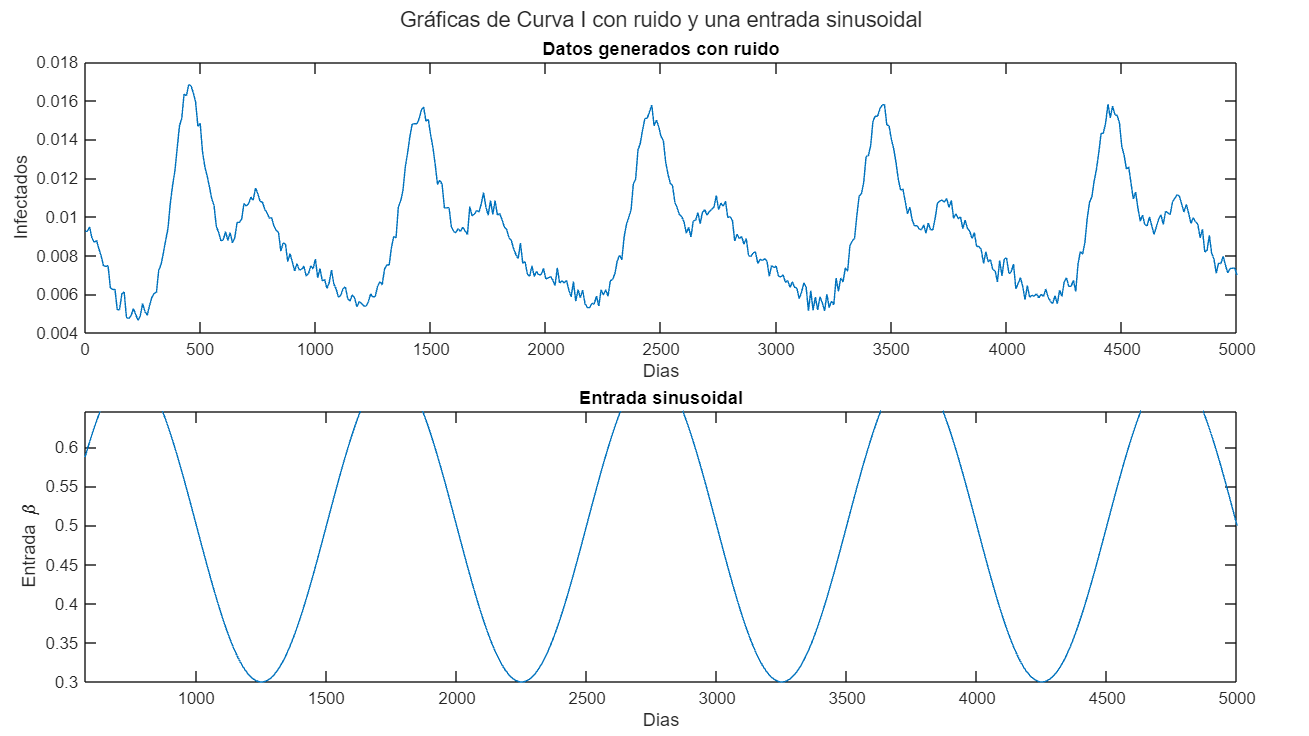

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");

nexttile
plot(t_escalon,Infectados_Seno),xlabel('Dias');ylabel('Infectados');title('Datos generados con ruido');

nexttile
plot(t_entrada,Entrada_Seno),xlabel('Dias');ylabel('Entrada \beta');title('Entrada sinusoidal');sgtitle('Gráficas de Curva I con ruido y una entrada sinusoidal');

tic
y=Y_PRBS;
N=length(y);
a1_min = 0.05; a1_max = 0.25;  ai_incr = 0.01; a1 = a1_min:ai_incr:a1_max; Na1 = length(a1);
a2_min = 0.05; a2_max = 0.25; a2_incr = 0.01; a2 = a2_min:a2_incr:a2_max; Na2 = length(a2);
Nsim = Na1*Na2;
V = zeros(Na1,Na2);



for i_a1=1:Na1
    
    for j_a2=1:Na2
        
        var_init(3)=a1(i_a1);
        var_init(4)=a2(j_a2);

        yest = sim("SEIRS_PRBS.slx").I.signals.values;
        V(i_a1,j_a2) = sum((y-yest).^2)/N; % Función de coste MSE
    end
 end
Vopt = min(V(:));
[i_a1_opt,j_a2_opt] = find(V==Vopt);
Par_opt = [a1(i_a1_opt) a2(j_a2_opt)];
t_fin = toc;
disp(['Tiempo de cómputo = ' num2str(t_fin/90) ' min'])

Tiempo de cómputo = 28.2454 min


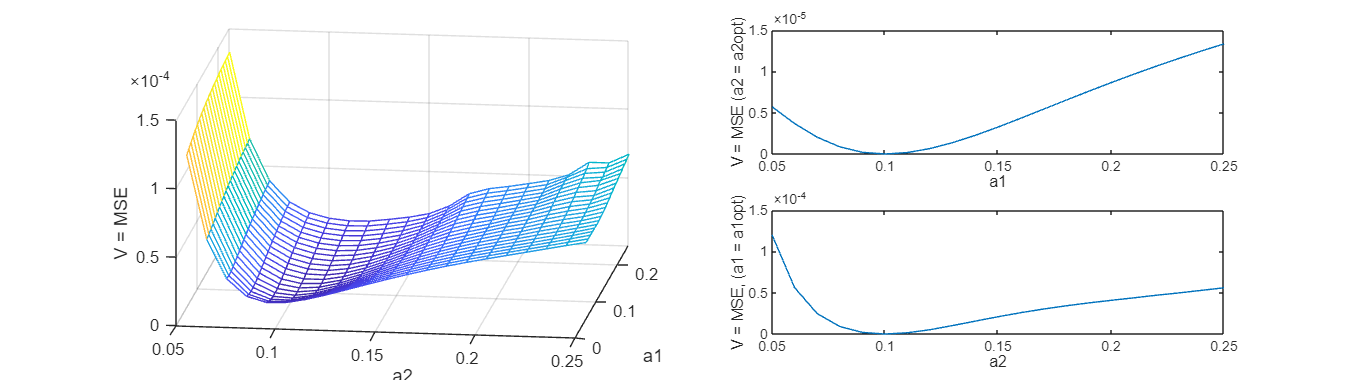

figure('Units','normalized','Position',[0 0 1 0.5])
subplot(2,2,[1 3])
mesh(a2,a1,V)
xlabel('a2'), ylabel('a1'), zlabel('V = MSE')
subplot(2,2,2)
plot(a1,V(:,j_a2_opt)), xlabel('a1'), ylabel('V = MSE (a2 = a2opt)')
subplot(2,2,4)
plot(a2,V(i_a1_opt,:)), xlabel('a2'), ylabel('V = MSE, (a1 = a1opt)')